addpath('./datos')
addpath('./funciones/')

% Cargo el fichero .wav
audio = "test_period_70.wav";
[xn fs_period] = audioread(audio);
xn=xn';

**FILTRO DE PREÉNFASIS:**

% FILTRO DE PREENFASIS --------------------------------
bk=[1 -0.86];
Hp=filter(bk,1,xn);
sn=Hp;
% plot(sn(1:250)),xlabel('n'),ylabel('s(n)'),grid;
% -----------------------------------------------------

% Definición e inicialización de variables
p=10;
Lframe=160;
Lsubframe=Lframe/4;
start_slice_subframe=1;
stop_slice_subframe=Lsubframe;
start_slice_frame=1;
stop_slice_frame=Lframe;
z = [];
zi = [];
dn = [];
E= [];
Er=[];
dp=zeros(1,120);
drp=zeros(1,120);
dpp=eps(1:40);
dr = [];
z2 = [];
sr = [];

**ANÁLISIS Y RECONSTRUCCIÓN :**

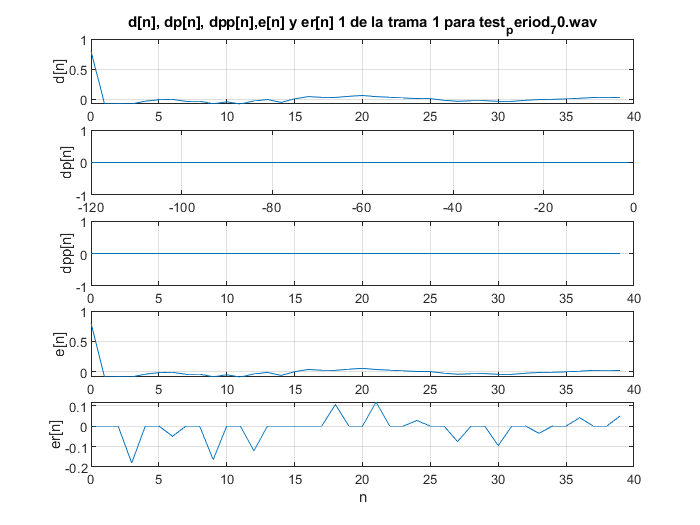

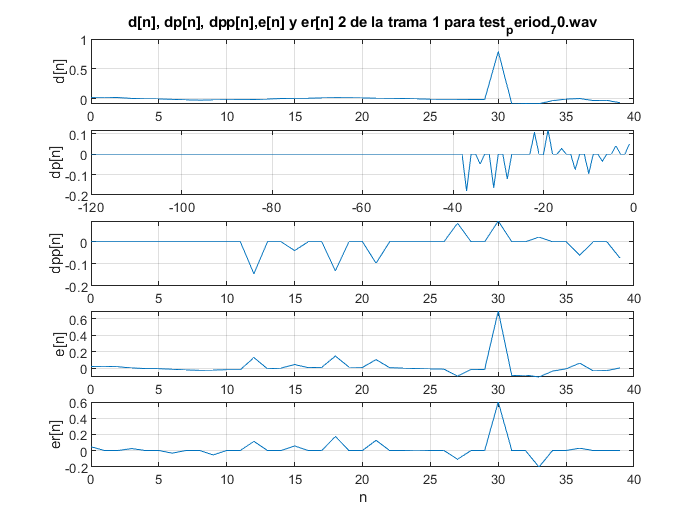

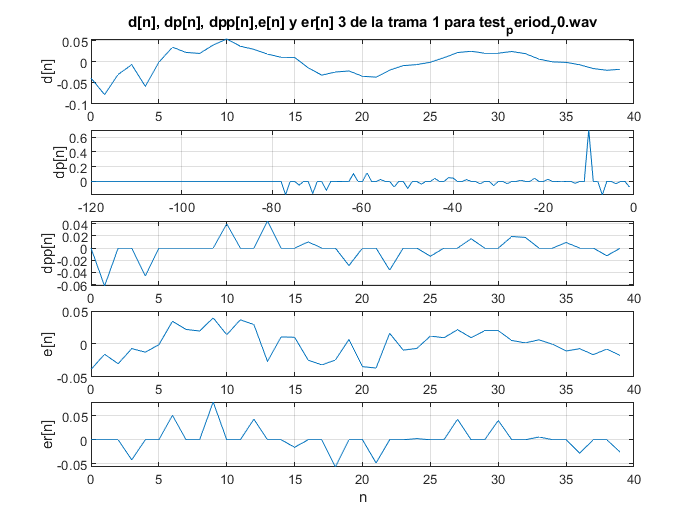

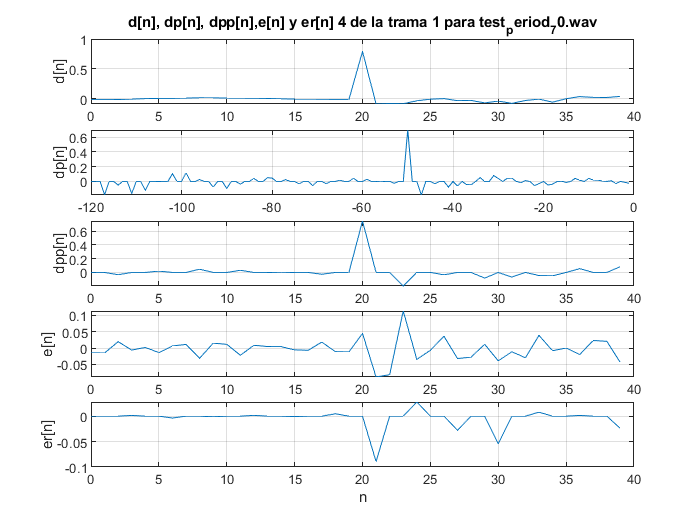

for i=1:floor(length(sn)/Lframe)
    
    % Para cada trama:
    frame=sn(start_slice_frame:stop_slice_frame);
    Rcorr=xcorr(frame,frame);
    Rcorr=Rcorr(length(frame):length(frame)+p);
    [ak,ep,rc] =levinson(Rcorr,p);
    LPC(i, :) = ak;
    [di zi]=filter(LPC(i,:),1,frame,zi);
    dn=[dn di];
    z=[z zi];
    
    for m=1:4
        
        % Para cada subtrama:
        dactual=di(Lsubframe*(m-1)+1:Lsubframe*m); % mediria 40
        R=xcorr(dactual,dp);
        [Rmax, Index]=max(R(40:120));
        % Index es respecto a 40, hay que sumarle 39 para obtener el retardo respecto a R.
        retardo=Index+39;
        dpN= dp(120 - retardo + 1 : 120 - retardo + 40);
        bi = Rmax/(sum(dpN.^2)+eps);
        dpp= dpN.*bi; 
        en=dactual-dpp;
        E= [E en];
        
        % Filtro de ponderación
        w=[-134, -374, 0, 2054, 5741, 8192, 5741, 2054, 0, -374, -134]/power(2,13);
        ew= conv(en,w,'same'); %convolución
        % Selección de pulsos
        cand=[ew(1:3:40-1);ew(2:3:40);ew(3:3:40);ew(4:3:40)];
        ew_sum=[(sum(cand(1,:))^2),(sum(cand(2,:))^2),(sum(cand(3,:))^2),(sum(cand(4,:))^2)];
        [ewmax, ind] =max(ew_sum);
        
        % Creación de ern interpolando ceros a la candidata seleccionada
        % Interpolo ceros -----------------------------------------
        ern = zeros(1,40);
        if ind == 1
            ern(1:3:40-1) = ew(1:3:40-1);
        else
            ern(ind:3:40) = ew(ind:3:40);
        end
        % ---------------------------------------------------------
        Er=[Er ern];

        if i<2
            figure;
            subplot(411),plot(0:39, dactual);xlabel('n');ylabel('d[n]'),grid,
            title("d[n], dp[n], dpp[n],e[n] y er[n] " + m + " de la trama " + i + " para " + audio)
            subplot(512),plot(-120:-1, dp);xlabel('n');ylabel('dp[n]'),grid,
            subplot(513),plot(0:39, dpp);xlabel('n');ylabel('dpp[n]'),grid,
            subplot(514),plot(0:39,en);xlabel('n');ylabel('e[n]'),grid;
            subplot(515),plot(0:39,ern);xlabel('n');ylabel('er[n]'),grid;
        end
        
        dp_last_subframe=ern+dpp; % la suma dpp+ern mide 40 ¿será la última trama de dp?
                   
%         drpN= drp(120 - retardo + 1 : 120 - retardo + 40);
%         drpp= dpp;
        
        dpanterior = dp (41:120);
        dp = [dpanterior dp_last_subframe];
        dr = [dr dp_last_subframe];
       
    end
    
    [sri z2]=filter(1, LPC(i,:), dr(start_slice_frame:stop_slice_frame),z2);
    sr = [sr sri];
    
    start_slice_frame = start_slice_frame+Lframe;
    stop_slice_frame = stop_slice_frame+Lframe;
    
end

**FILTRO DE DEÉNFASIS:**

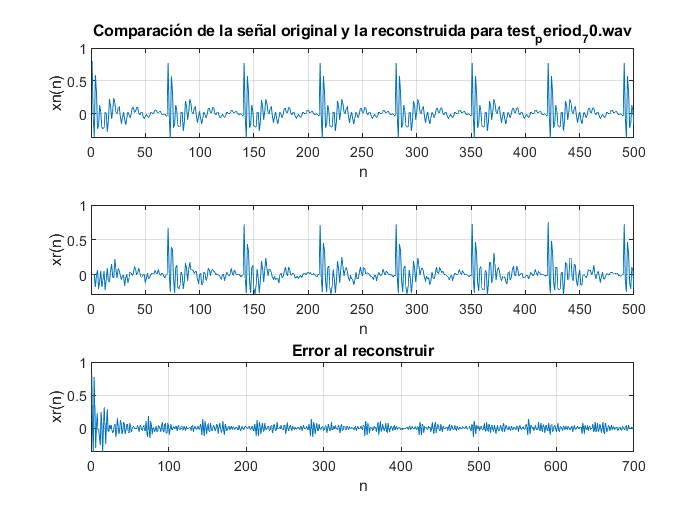

bk=[1 -0.86];
xr=filter(1,bk,sr);

% figure
% plot(xr(1:250)),xlabel('n'),ylabel('xr(n)'),grid,
a=xn(1:length(xr))-xr;
figure
subplot(311),plot(xn(1:500));xlabel('n');ylabel('xn(n)'),grid,
title('Comparación de la señal original y la reconstruida' + " para " + audio)
subplot(312), plot(xr(1:500)); xlabel('n'); ylabel('xr(n)'), grid,
subplot(313),plot(a(1:700)); xlabel('n'); ylabel('xr(n)'), grid,
title('Error al reconstruir')

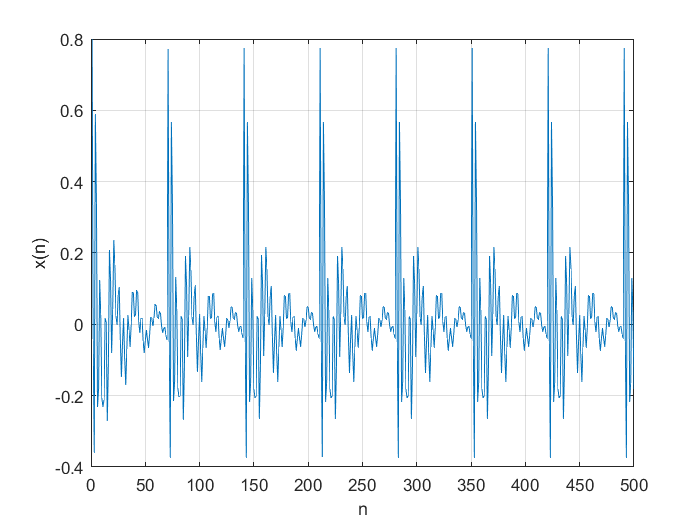

figure
plot(xn(1:500));xlabel('n');ylabel('x(n)'),grid;

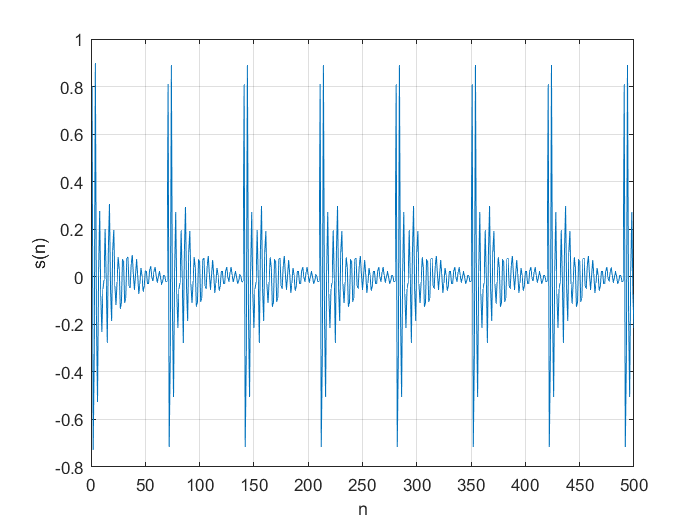


figure
plot(sn(1:500));xlabel('n');ylabel('s(n)'),grid;

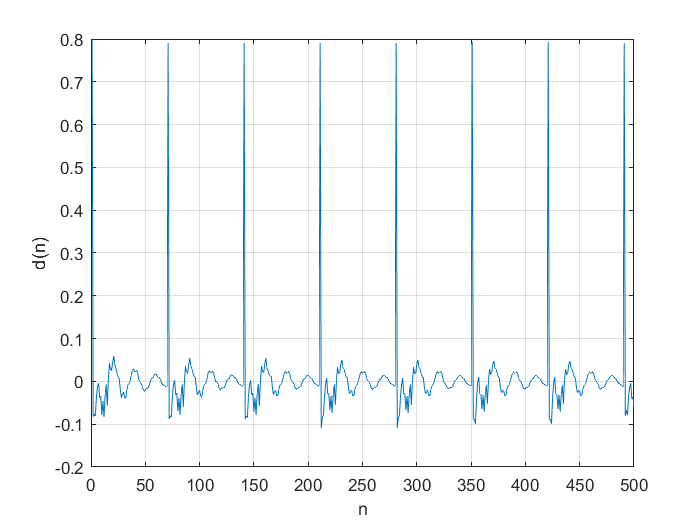


figure
plot(dn(1:500)); xlabel('n'); ylabel('d(n)'), grid;

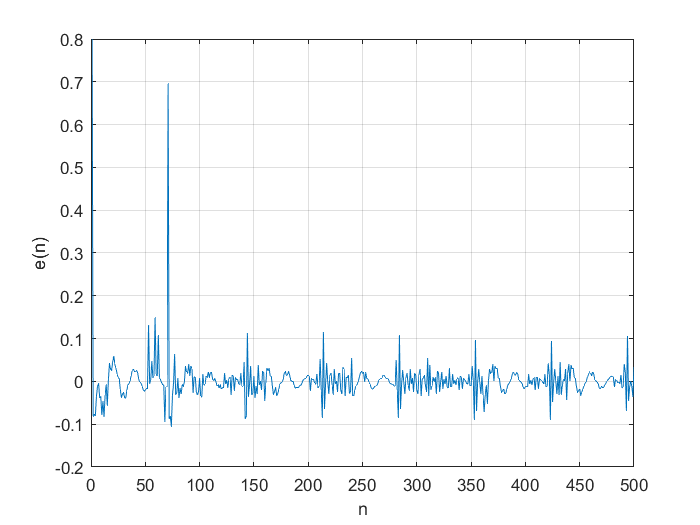


figure
plot(E(1:500));xlabel('n');ylabel('e(n)'),grid;

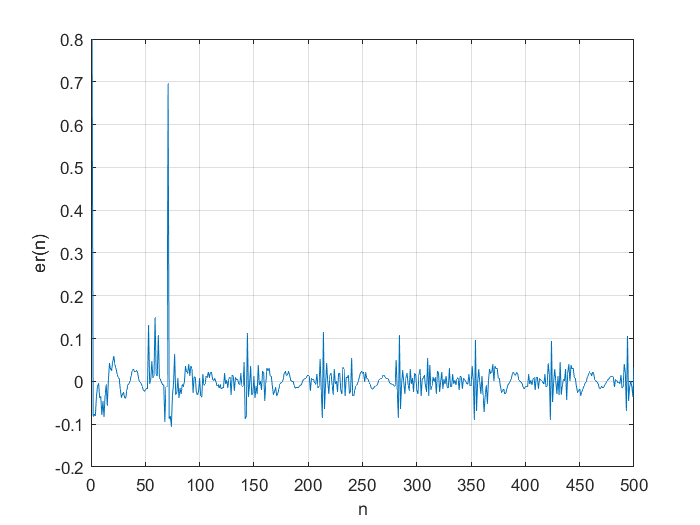


figure
plot(E(1:500));xlabel('n');ylabel('er(n)'),grid;

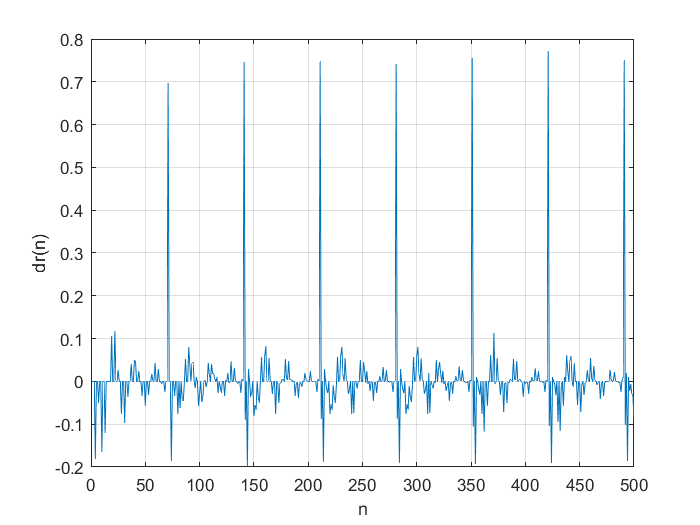


figure
plot(dr(1:500));xlabel('n');ylabel('dr(n)'),grid;

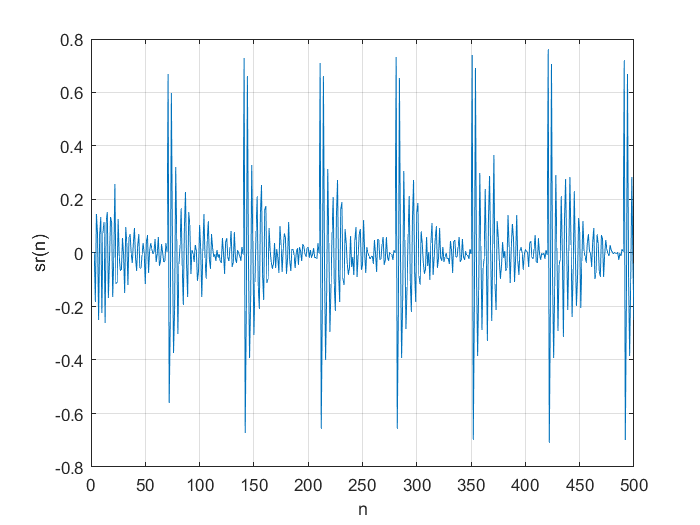


figure
plot(sr(1:500));xlabel('n');ylabel('sr(n)'),grid;

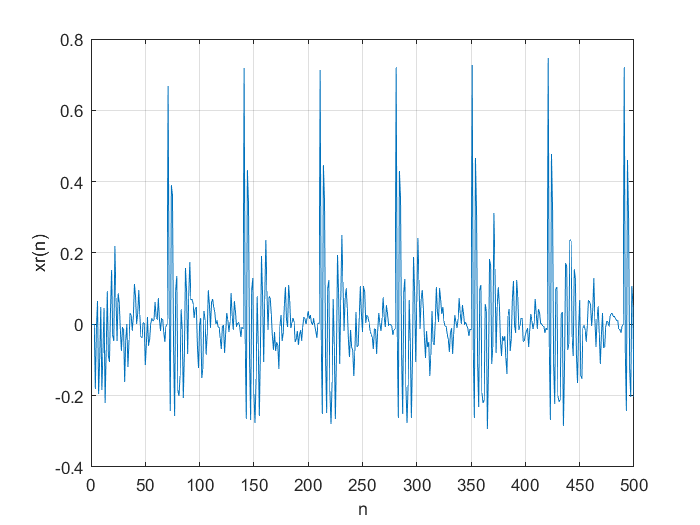


figure
plot(xr(1:500));xlabel('n');ylabel('xr(n)');grid;

**SNR:**

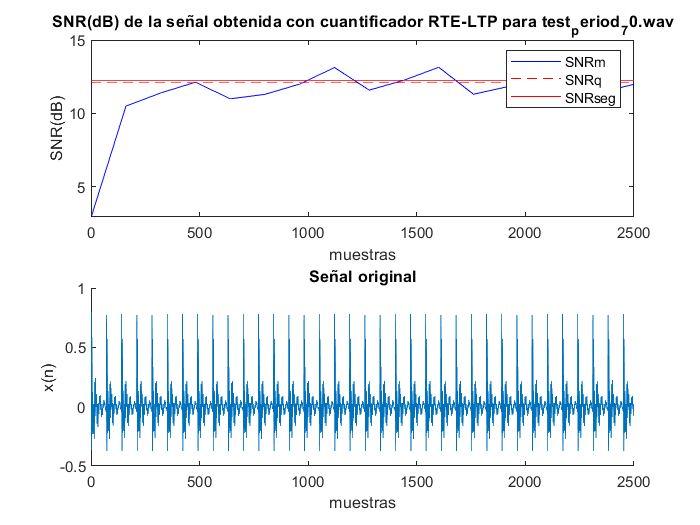

P=10;
xna=xn(1:length(xr));
SNRq = SNR(xna',xr);
[SNRseg,SNRm,m] = SNRS(xna',xr,Lframe);
vectorxn = 1:length(xna);
figure;
%Subgrafica superior
subplot 211;
plot(m, SNRm,'b'); %SNRm riser
hold on
plot(m,ones(size(m))*(SNRq),'r--');  %SNRGlobal
plot(m,ones(size(m))*(SNRseg),'r');  %SNRSeg tread
title('SNR(dB) de la señal obtenida con cuantificador RTE-LTP' + " para " + audio);
xlabel('muestras');
ylabel('SNR(dB)');
% ylim([295 380]);
xlim([0 2500]);
legend('SNRm','SNRq','SNRseg')
%Subgrafica inferior
subplot 212;
hold on
plot(xna(1:2500)); %Senal original
title('Señal original'); xlabel('muestras'); ylabel('x(n)');
hold off